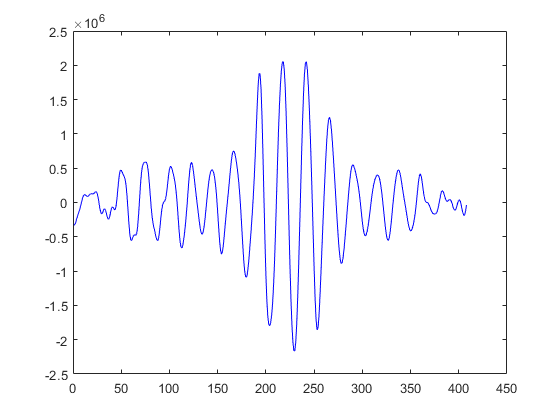

%%  SSA tutorial with Matlab
% This Matlab tutorial demonstrates step by step the Singular Spectrum
% Analysis (SSA).
%
% *References*
%
% [1] Groth, A., and M. Ghil, 2015: Monte Carlo Singular Spectrum Analysis (SSA) revisited: Detecting oscillator clusters in multivariate datasets, Journal of Climate, 28, 7873-7893.
%
% Find more research on Singular Spectrum Analysis and related topics at
% <https://dept.atmos.ucla.edu/tcd>

%% Set general Parameters
M = 30;    % window length = embedding dimension
N = 200;   % length of generated time series
T = 22;    % period length of sine function
stdnoise = 1; % noise-to-signal ratio


% if (exist("data","var") == 0)
%     data = (load("c_2013_11_16_04.dat"))';
% end
fs = 187;
data = data_filtered_ROI;
window = fs*2;

% %% Set general Parameters
% M = fs * 2;    % window length = embedding dimension
% N = fs* 10;   % length of generated time series
% T = 22;    % period length of sine function
% stdnoise = 1; % noise-to-signal ratio

% tx = linspace(0,length(data)/fs, length(data));

N = length(data);
%% Create time series X
% First of all, we generate a time series, a sine function of length N with
% observational white noise

t = (1:N)';

X = sin(2*pi*t/T);
noise = stdnoise*randn(size(X));
X = X + noise;
X = X - mean(X);            % remove mean value
X = X/std(X,1);             % normalize to standard deviation 1

X = data(1:N);
figure(1);
set(gcf,'name','Time series X');
clf;
plot(t,X,'b-');



%% Calculate covariance matrix C (Toeplitz approach)
% Next, we calculate the covariance matrix. There are several numerical
% approaches to estimate C. Here, we calculate the covariance function with
% CORR and build C with the function TOEPLITZ.

covX = xcorr(X,M-1,'unbiased');
Ctoep=toeplitz(covX(M:end));

figure(2);
set(gcf,'name','Covariance matrix');
clf;
imagesc(Ctoep);
axis square
set(gca,'clim',[-1 1]);
colorbar

%% Calculate covariance matrix (trajectory approach)
% An alternative approach is to determine C directly from the scalar
% product of Y, the time-delayed embedding of X. Although this estimation
% of C does not give a Toeplitz structure, with the eigenvectors not being
% symmetric or antisymmetric, it ensures a positive semi-definite covariance
% matrix.
figure(2);
Y=zeros(N-M+1,M);
for m=1:M    
  Y(:,m) = X((1:N-M+1)+m-1);
end;
Cemb=Y'*Y / (N-M+1);


set(gcf,'name','Covariance matrix');
clf;
imagesc(Cemb);
axis square
set(gca,'clim',[-1 1]);
colorbar

%% Choose covariance estimation
% Choose between Toeplitz approach (cf. Vautard & Ghil) and trajectory
% approach (cf. Broomhead & King).

% C=Ctoep;
C=Cemb;

%% Calculate eigenvalues LAMBDA and eigenvectors RHO
% In order to determine the eigenvalues and eigenvectors of C, we use the
% function EIG. This function returns two matrices, the matrix RHO with
% eigenvectors arranged in columns, and the matrix LAMBDA with eigenvalues
% along the diagonal.

[RHO,LAMBDA] = eig(C);
LAMBDA = diag(LAMBDA);               % extract the diagonal elements
[LAMBDA,ind]=sort(LAMBDA,'descend'); % sort eigenvalues
RHO = RHO(:,ind);                    % and eigenvectors

figure(3);
set(gcf,'name','Eigenvectors RHO and eigenvalues LAMBDA')

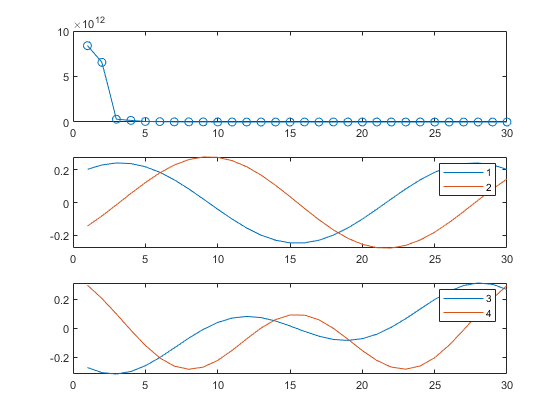

clf;
subplot(3,1,1);
plot(LAMBDA,'o-');
subplot(3,1,2);
plot(RHO(:,1:2), '-');
legend('1', '2');
subplot(3,1,3);
plot(RHO(:,3:4), '-');
legend('3', '4');

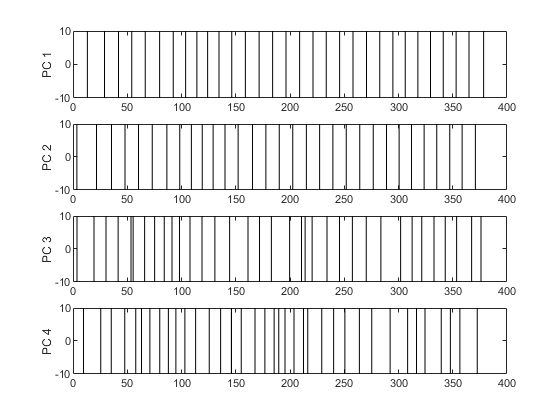


%% Calculate principal components PC
% The principal components are given as the scalar product between Y, the
% time-delayed embedding of X, and the eigenvectors RHO.

PC = Y*RHO;
figure(4);

set(gcf,'name','Principal components PCs')
clf;
for m=1:4
  subplot(4,1,m);
  plot(t(1:N-M+1),PC(:,m),'k-');
  ylabel(sprintf('PC %d',m));
  ylim([-10 10]);
end;

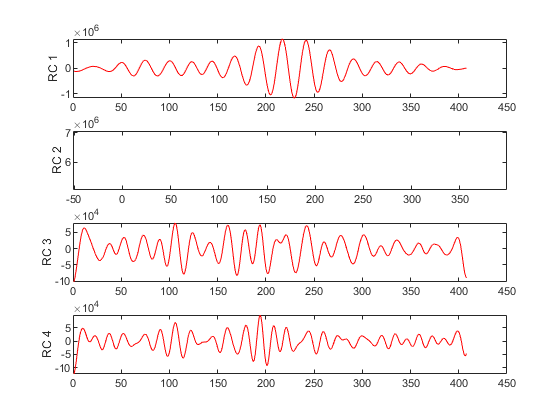



%% Calculate reconstructed components RC
% In order to determine the reconstructed components RC, we have to invert
% the projecting PC = Y*RHO; i.e. RC = Y*RHO*RHO'=PC*RHO'. Averaging along
% anti-diagonals gives the RCs for the original input X.

RC=zeros(N,M);
for m=1:M
  buf=PC(:,m)*RHO(:,m)'; % invert projection
  buf=buf(end:-1:1,:);
  for n=1:N % anti-diagonal averaging
    RC(n,m)=mean( diag(buf,-(N-M+1)+n) );  
  end
end;

figure(5);
set(gcf,'name','Reconstructed components RCs')
clf;
for m=1:4
  subplot(4,1,m);
  plot(t,RC(:,m),'r-');
  ylabel(sprintf('RC %d',m));
  %ylim([-1 1]);
end;

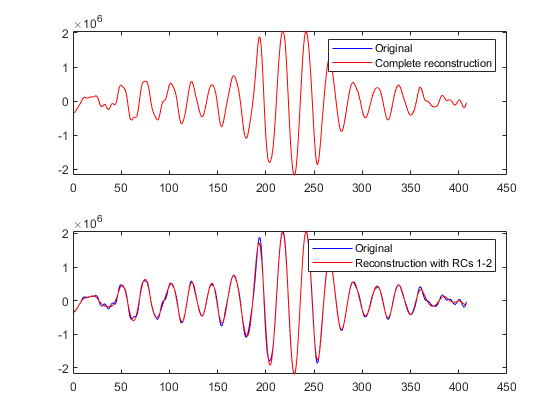


%% Compare reconstruction and original time series
% Note that the original time series X can be completely reconstructed by
% the sum of all reconstructed components RC (upper panel). The sine
% function can be reconstructed with the first pair of RCs (lower panel).

figure(6);
set(gcf,'name','Original time series X and reconstruction RC')
clf;
subplot(2,1,1)
plot(t,X,'b-',t,sum(RC(:,:),2),'r-');
legend('Original','Complete reconstruction');

subplot(2,1,2)
plot(t,X,'b','LineWidth',2);
plot(t,X,'b-',t,sum(RC(:,1:4),2),'r-');
legend('Original','Reconstruction with RCs 1-2');


for i=1:length(RHO)
    figure(7)
    title("RHO no: " + i);
    plot(t,X,'b-',t,sum(RC(:,i),2),'r-');
    legend('Original','Complete reconstruction');
    pause(1);
    clf;
end